# Ballbot robust stability analysis and validation script

**Contents:**

- Nonlinear model synthesis with distrubances

- Parametric linearisation 

- Parametric uncertainty introduction

- optimisation based worst case search

- Disturbance rejection and noise attenutation

- H-infinity controller synthesis

- based on linear systems 

- based on worst case system

- Comparison of behavior with nonlinear model

clear all
mkdir('generated')

addpath('./generated')
addpath('./visualisation')
addpath('./optimisation')

## Model physical parameters definition

Introducing the physical parameters of the system

global rK_n rW_n  rA_n  l_n  mAW_n mK_n  A_ThetaAWx_n  A_ThetaAWy_n  A_ThetaAWz_n  ThetaKi_n  ThetaWi_n;

% Uncertain parameters
rK_n = 0.120; % radius of the ball
rW_n = 0.05; % radius of omni wheel=5cm
rA_n = 0.126; % radius of the body  
l_n = 0.22634; % distance between centre of ball and centre of gravity of the body 
mAW_n = 6.71; % mass of the body and omni wheel  
mK_n = 0.625; % mass of the basket ball  
A_ThetaAWx_n = 1.41271413; % Inertia of the body and Omni wheels in the body reference frame A  
A_ThetaAWy_n = 1.41271311;
A_ThetaAWz_n = 0.05359646;
ThetaKi_n = 0.003606375;
ThetaWi_n = 0.01504; 

% Angle of motors
alpha = 47*pi/180;
beta1 = 0;
beta2 = 2/3*pi;
beta3 = 4/3*pi;

% vector of nominal parameters
params_n = [rK_n, rW_n, rA_n, l_n, mAW_n, mK_n, A_ThetaAWx_n, A_ThetaAWy_n, A_ThetaAWz_n, ThetaKi_n, ThetaWi_n];

## Derivation script of the nonlinear model

Modeling ot the nonlinear system - extended matlab version of the script FInal.nb made in Mathematica

- Parametric nonlinear model creation

- Linearization around 0

- Creation of simulation functions for further analyisis - linear and nonlinear

Execution can take 5-10 minutes

model_generation;

Model physical parameters
Coordinate system transformations
Binding equations


Energies
Non-potential forces
Lagrange


Elapsed time is 4.068601 seconds.
Linear equation solving
Elapsed time is 8.394419 seconds.
State space representation
Elapsed time is 51.504774 seconds.
Creating a matlab function from nonlinear model
This may take few minutes
Elapsed time is 64.963777 seconds.
Adding linearisation point
Linearisation x0
A matrix
10/10
Elapsed time is 31.009642 seconds.
B matrix
Elapsed time is 3.748223 seconds.
W matrix
Elapsed time is 1.564096 seconds.
Create A and B and W parametric functions - physical parameters
Elapsed time is 22.462638 seconds.
Model script done


## Linear nominal model sysnthesys

Creation of linear transfer funciton based on linearised matrices of the Ballbot and the nominal parameters

Additionally the LQR controller is provided (based on the LQR controller in the report) as a default controller to be compared in further analysis.


% A matrix
tic
A_n= fA(rK_n, rW_n, rA_n, l_n, mAW_n, mK_n, A_ThetaAWx_n, A_ThetaAWy_n, A_ThetaAWz_n, ThetaKi_n, ThetaWi_n);
fprintf('A matrix :  %f sec\n',toc);

A matrix :  0.417284 sec


% B matrix
tic
B_n= fB(rK_n, rW_n, rA_n, l_n, mAW_n, mK_n, A_ThetaAWx_n, A_ThetaAWy_n, A_ThetaAWz_n, ThetaKi_n, ThetaWi_n);
fprintf('B matrix :  %f sec\n',toc);

B matrix :  1.029661 sec


% B_w matrix
tic
B_w= fW(rK_n, rW_n, rA_n, l_n, mAW_n, mK_n, A_ThetaAWx_n, A_ThetaAWy_n, A_ThetaAWz_n, ThetaKi_n, ThetaWi_n);
fprintf('B_w matrix :  %f sec\n',toc);

B_w matrix :  0.368639 sec



% state space model from matrices
G_n = ss(A_n, B_n, eye(10), zeros(10,3));


LQR controller synthesis


% LQR controller design
Q = diag([100 50 100 50 40 20 20 10 20 10]);
R = diag([100 100 100]);
K_lqr = lqr(G_n,Q,R);

## Linear and nonlinear model initial condition response comparison

Finally, simple graph of initial condition response for linear and nonlinear system with nominal parameters to see how well does the lienarized system corespond with the nonlinear

nonlinear system simulation
Nonlinear simulation: 4.00 sec / 4.00 sec
Elapsed time is 32.605480 seconds.
lienar system simulation
Elapsed time is 0.462102 seconds.


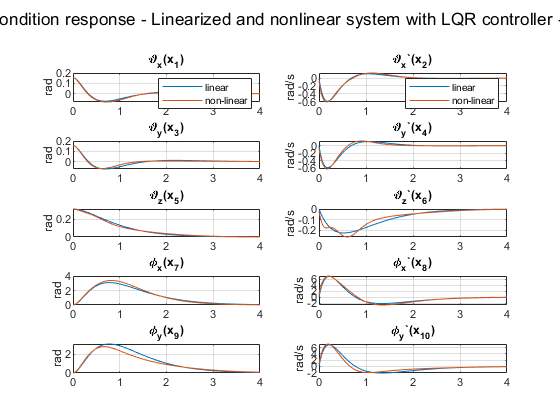

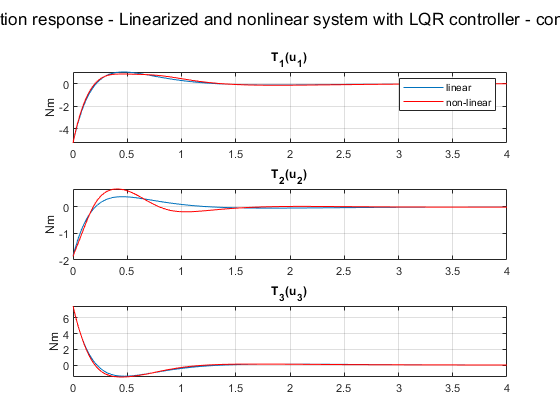

X0 = [pi/20 0 pi/20 0 pi/10 0 0 0 0 0]';
T_max = 4; %s
initialplot_compare_nlin(@nlin_model_n,G_n,K_lqr,X0,T_max,1,2)

drawnow

## Introducing the uncertainties

The uncertainties are introduced into the physiscal parameters of the system. The idea is that for the variables you cannot measure you should have some uncertainty about their values. 

The uncertainties are set as the percentage. For example if l_var is 20, that means that your height of center of mass can be +-20% different than your nominal value.

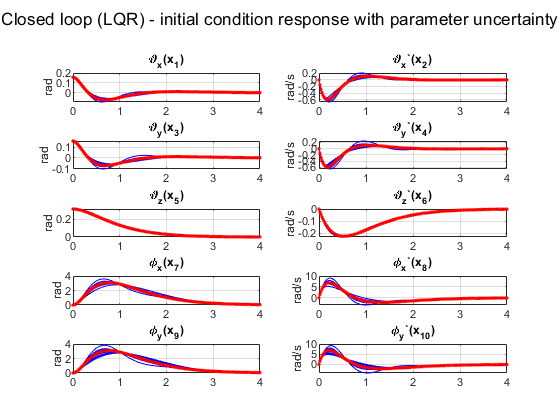

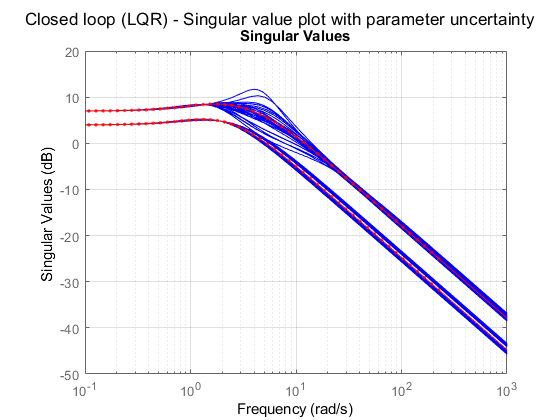

Sample uncertain models
Uncertain model visualisation - initial condition response
It may take few minutes


Elapsed time is 10.887347 seconds.
Uncertain model visualisation - singular value plot
It may take few minutes


Elapsed time is 12.276194 seconds.


% Uncertain variation of the parameters
l_var = 18; % percent
A_ThetaAWx_var = 18; % percent
A_ThetaAWy_var = 18; % percent
A_ThetaAWz_var = 18;% percent
ThetaKi_var = 18;% percent
ThetaWi_var = 18;% percent

% sample the uncertain models
kill_figures([100,101]);
visualise_uncertainty(l_var, ThetaWi_var, ThetaKi_var, A_ThetaAWx_var, A_ThetaAWy_var, A_ThetaAWz_var, K_lqr,100,101);

## Find the worst case system based on parameter uncertainties

To be able to find the worst case parameters we define the optimisation problem based on disk margin. 

Basically we are changing the parameter values and searching to the minimum of the stability margin (diskmargin)

The minimal margin corresponds to the worst case parameters

wcu = find_wcu_optimisation(l_var, ThetaWi_var, ThetaKi_var, A_ThetaAWx_var, A_ThetaAWy_var, A_ThetaAWz_var, K_lqr)

Constrained optimisation approach to finding worst case condition

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      7      0.11011     -0.02299                                         
    1     14    0.0471509            0            1       -0.347        0.149   
    2     21    0.0471424            0            1     -0.00301      0.00396  Hessian modified  
    3     28    0.0471399            0            1     -0.00184      0.00296  Hessian modified  
    4     35    0.0470819            0            1     -0.00156      0.00988  Hessian modified  
Active inequalities (to within options.ConstraintTolerance = 1e-06):
  lower      upper     ineqlin   ineqnonlin
    1          2                      
    3          4                      

Local minimum possible. Constraints

X =     0.8200    1.1800    0.8200    1.1800    1.0631    1.1335


FVAL = 0.0471

EXITFLAG = 5

Construct the worst case sample


wcu = struct with fields:
             l: 0.1856
       ThetaWi: 0.0177
       ThetaKi: 0.0030
    A_ThetaAWx: 1.6670
    A_ThetaAWy: 1.5019
    A_ThetaAWz: 0.0608
    min_margin: 0.0471
             G: [10×3 ss]
      max_gain: 8.4792


% variable wcu contains 
% wcu.l,ThetaKi,... - the worst case parameters 
% wcu.min_margin    - worst case margin
% wcu.max_gain      - worst case gain
% wcu.G             - linear state space model of the worst case transfer function



## Nominal and worst case linear model comparison

#### Margin comparison

% nominal parameters
MMIO_n = diskmargin(G_n,K_lqr)

MMIO_n = struct with fields:
     GainMargin: [0.8536 1.1715]
    PhaseMargin: [-9.0299 9.0299]
     DiskMargin: 0.1579
     LowerBound: 0.1579
     UpperBound: 0.1582
      Frequency: 3.5389


%worst case parameters
MMIO_wc = diskmargin(wcu.G,K_lqr)

MMIO_wc = struct with fields:
     GainMargin: [0.9540 1.0482]
    PhaseMargin: [-2.6971 2.6971]
     DiskMargin: 0.0471
     LowerBound: 0.0471
     UpperBound: 0.0472
      Frequency: 4.4176


#### Initial condition response

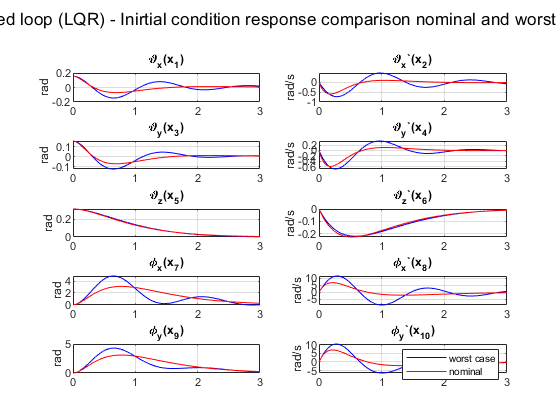

 % initialplot
X0 = [pi/20 0 pi/20 0 pi/10 0 0 0 0 0]';
T_sim = 3; %sec=
kill_figures([110])
initialplt(feedback(wcu.G,K_lqr),'b',X0,T_sim,110); 
initialplt(feedback(G_n,K_lqr),'r',X0,T_sim,110);
legend('worst case','nominal')
sgtitle('Closed loop (LQR) - Inirtial condition response comparison nominal and worst case')

#### Singular value plota

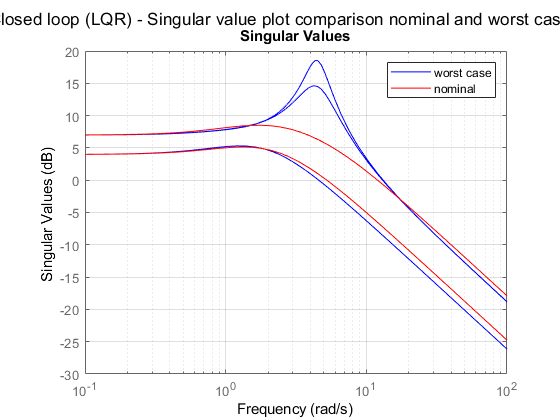

kill_figures([111]);
figure(111);
sigma(feedback(wcu.G,K_lqr),'b');
hold on;
sigma(feedback(G_n,K_lqr),'r');
legend('worst case','nominal')
grid on;
sgtitle('Closed loop (LQR) - Singular value plot comparison nominal and worst case')

## Validate worst case performance with the nonlinear model

Interesting is to see if nonlinear system is still stable for worst case parameters and LQR controller calculated for the nominal parameters.

% generate the worst  case parameters nonlinear model ans save it to  nlin_model_wcu function
model_generation_worst_case;

Creating a matlab function from nonlinear model
This may take few minutes
Writing function in the file
Elapsed time is 95.109020 seconds.


kill_figures([120,121]);
% Simulate and compare worst case linear and nonliner
initialplot_compare_nlin(@nlin_model_wcu,wcu.G,K_lqr,X0,T_sim,120,121)

nonlinear system simulation
Nonlinear simulation: 3.00 sec / 3.00 sec
Elapsed time is 41.198434 seconds.
lienar system simulation
Elapsed time is 0.013206 seconds.


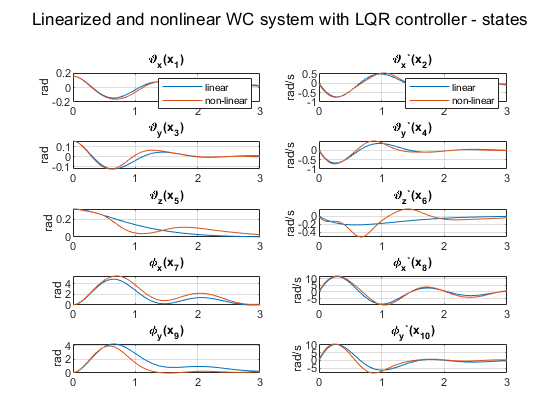

figure(120);
sgtitle('Linearized and nonlinear WC system with LQR controller - states')

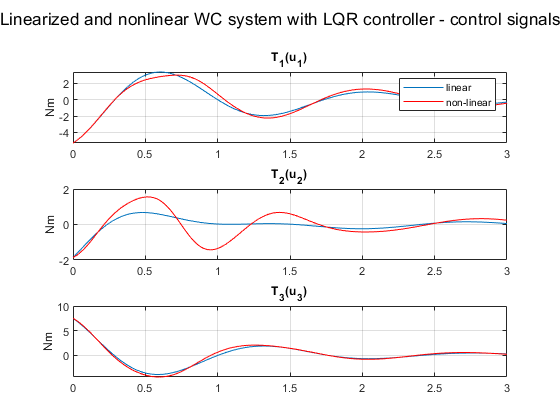

figure(121);
sgtitle('Linearized and nonlinear WC system with LQR controller - control signals')
drawnow

# Distrubance rejection and noise attenuation

#### **Ballbot has two type of disturbance **

 - ***force acting on the body - hunam interaction ****(w)*

 - ***measurement noise *** (*n*)

   > acceletometer and gyro

   > influences thetax, d_thetax, thetay, d_thetay  

#### ** Ballbot system**

 dx = Ax + [B_n B_w B_u]*[w n u]'

 y = Cx + [D_n D_w D_u]*[w n u]'

 u = K*x

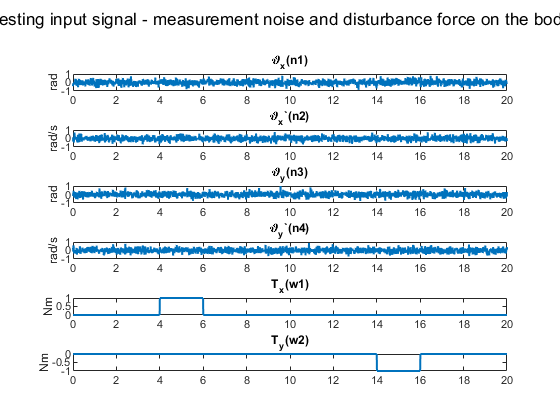

% definining the standardized testing input for distrubance rejection
t_d = linspace(0,20,2000);
N_d = length(t_d);
n = randn(4,N_d);
n = n/max(n(:));
wx = [zeros(1,0.2*N_d), ones(1,0.1*N_d), zeros(1,0.7*N_d)];
wy = [zeros(1,0.7*N_d), -ones(1,0.1*N_d) zeros(1,0.2*N_d)];
dist = [n; wx; wy];

kill_figures([200]);
figure(200);
state_var_names = {'\vartheta_x', '\vartheta_x`','\vartheta_y', '\vartheta_y`'};
for i = 1:4
    subplot(6,1,i);
    plot(t_d,dist(i,:),'LineWidth',1.5);
    hold on
    title(strcat(state_var_names{i},'(n',num2str(i),')'))
    if mod(i,2)
        ylabel('rad')
    else
        ylabel('rad/s')
    end
end
w_names={'T_x','T_y'};
for i = 1:2
    subplot(6,1,4+i);
    plot(t_d,dist(4+i,:),'LineWidth',1.5);
    hold on
    title(strcat(w_names{i},'(w',num2str(i),')'))
    ylabel('Nm')
end
sgtitle('Testing input signal - measurement noise and disturbance force on the body')

## Creating the factorial representaion

%% disturbance matrix
B_w = fW(rK_n, rW_n, rA_n, l_n, mAW_n, mK_n, A_ThetaAWx_n, A_ThetaAWy_n, A_ThetaAWz_n, ThetaKi_n, ThetaWi_n);
% noise matrix
B_n = zeros(10,4);
% measurement noise variance 1 degree 
D_n = 0.5/180*pi*eye(10,4); 
% input D matrix
D_u = zeros(10,5);
C_y = [G_n.c; zeros(3,10)];
D_y = [D_n  D_u ; [zeros(3,6) eye(3)]];
% model for simulation using y as output
P = ss(G_n.a, [B_n B_w G_n.b], [C_y; G_n.c], [ D_y; [D_n D_u] ]);

% worst case model
% disturbance matrix
B_w_wcu = fW(rK_n, rW_n, rA_n, wcu.l, mAW_n, mK_n, wcu.A_ThetaAWx, wcu.A_ThetaAWy, wcu.A_ThetaAWz, wcu.ThetaKi, wcu.ThetaWi);
% model for simulation using y as output
P_wc = ss(wcu.G.a, [B_n B_w_wcu wcu.G.b], [C_y; wcu.G.c], [ D_y; [D_n D_u]]);

% scaled models for h-infinty controller optimisation
H_lqr = lft(P,-K_lqr);
W = ones(1,13);
for i=1:13
   W(i) = max(min(1/hinfnorm(H_lqr(i,:)),10),1);
end
C_z = [diag(W(1:10)); zeros(3,10)];
D_z = [D_n  D_u ; [zeros(3,6) diag(W(11:13))]];
% model for h-infinity synthesis containing z output
Pz = ss(G_n.a, [B_n B_w G_n.b], [C_z; G_n.c], [ D_z; [D_n D_u] ]);
% model for h-infinity synthesis containing z output
Pz_wc = ss(wcu.G.a, [B_n B_w_wcu wcu.G.b], [C_z; wcu.G.c], [ D_z; [D_n D_u]]);

## Initial LQR disturbance rejection

Compariosn of linear and nonliner performcane using nominal and worst case parameters

kill_figures([201,202,203,204]);
% complarison linear nonlinear disturbance rejection
nlsim(@nlin_model_n,-K_lqr,dist,t_d,P,201,202);

nonlinear system simulation
Nonlinear simulation: 20.00 sec / 20.00 sec
Elapsed time is 49.309889 seconds.


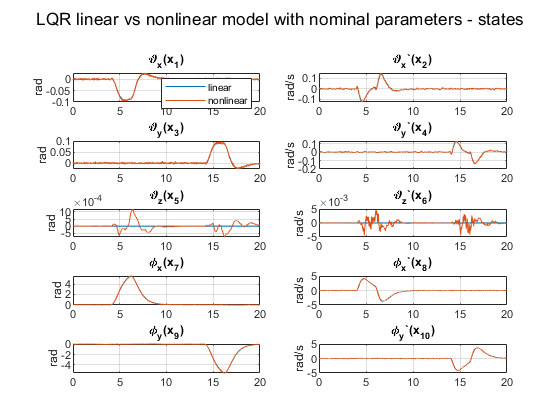

figure(201)
sgtitle('LQR linear vs nonlinear model with nominal parameters - states')

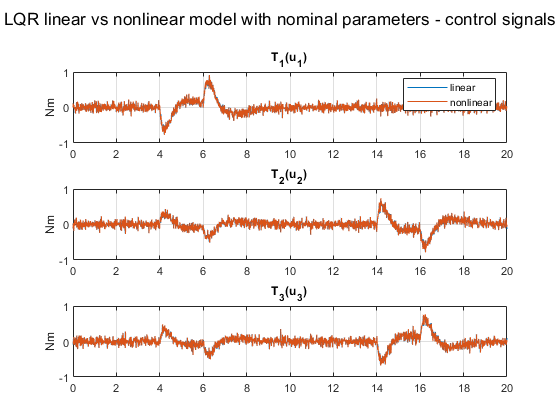

nonlinear system simulation
Nonlinear simulation: 20.00 sec / 20.00 sec
Elapsed time is 47.446068 seconds.


figure(202)
sgtitle('LQR linear vs nonlinear model with nominal parameters - control signals')
% complarison linear nonlinear disturbance rejection
nlsim(@nlin_model_wcu,-K_lqr,dist,t_d,P_wc,203,204);

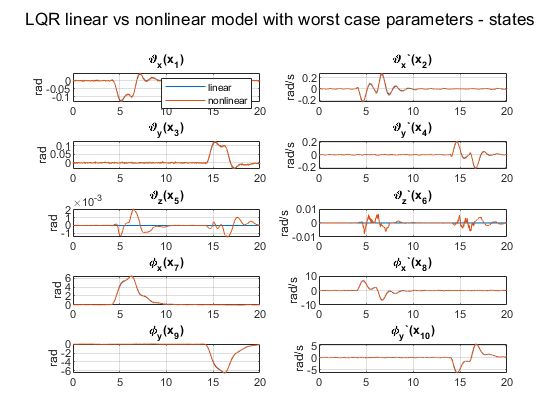

figure(203)
sgtitle('LQR linear vs nonlinear model with worst case parameters - states')

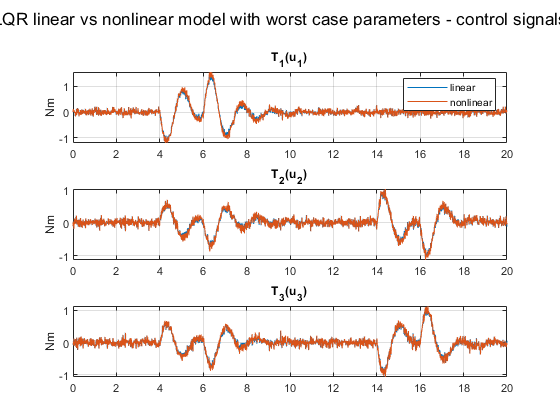

figure(204)
sgtitle('LQR linear vs nonlinear model with worst case parameters - control signals')

### Singular value plot for disturbance rejection fonominal and worst case model

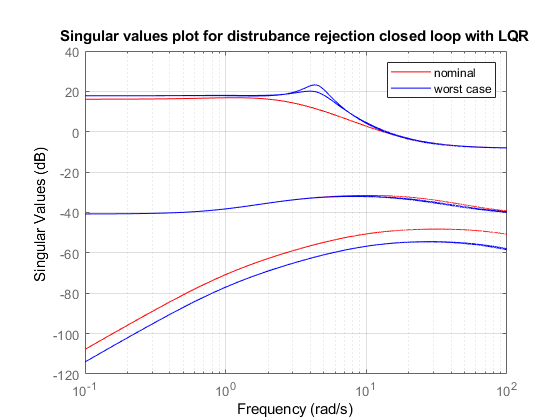

% plot singular values of distrurbance rejection loop
figure(301)
sigma(lft(P,-K_lqr),'r',lft(P_wc,-K_lqr),'b',(0.1:0.01:100));
legend('nominal','worst case');
grid on
title('Singular values plot for distrubance rejection closed loop with LQR')

## H-infinity controller design

Fixed structure - gain U=K*x;

%% H-infinity controller design fixed
% hinf fixed structure - gain
K_tun = realp('K_t',K_lqr);   
K_tun.Minimum = -50*ones(3,10); 
K_tun.Maximum = 50*ones(3,10);
opts = hinfstructOptions('TargetGain',0,'MaxIter',1000,'RandomStart',10,'MaxFrequency',10);
[C,gamma,info] = hinfstruct(Pz_wc,-K_tun,opts);

Final: Peak gain = 6.08, Iterations = 428
Final: Peak gain = 6.03, Iterations = 652
Final: Peak gain = 6.08, Iterations = 513
Final: Peak gain = 6.13, Iterations = 654
Final: Peak gain = 6.13, Iterations = 755
Final: Failed to enforce closed-loop stability (max Re(s) = 0.19)
Final: Failed to enforce closed-loop stability (max Re(s) = 0.69)
Final: Peak gain = 6.05, Iterations = 610
Final: Peak gain = 6.17, Iterations = 577
Final: Peak gain = 6.14, Iterations = 679
Final: Peak gain = 6.03, Iterations = 665


K_hinf = C.Blocks.K_t.Value

K_hinf =    49.9255   13.1307  -11.4381   -0.6456  -49.6145  -24.8893    0.1236    1.0765    0.5075   -0.7273
  -49.8621  -33.7944   47.9807   43.7370   49.9998  -12.0289   -0.1184   -1.7909    0.0223    2.4824
  -49.9962   -1.1057  -49.9994  -49.5533  -31.1691   24.5894   -1.0649   -0.3999   -0.2531   -2.4783


## **Comparison of H-infinity and LQR **

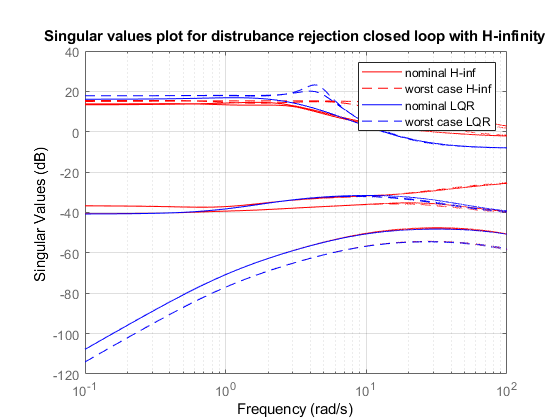

% plot singular values of distrurbance rejection loop
figure(302)
sigma(lft(P,-K_hinf),'r',lft(P_wc,-K_hinf),'--r',lft(P,-K_lqr),'b',lft(P_wc,-K_lqr),'--b',(0.1:0.01:100));
legend('nominal H-inf','worst case H-inf','nominal LQR','worst case LQR');
grid on
title('Singular values plot for distrubance rejection closed loop with H-infinity')

## Complarison H-infinity and LQR linear models

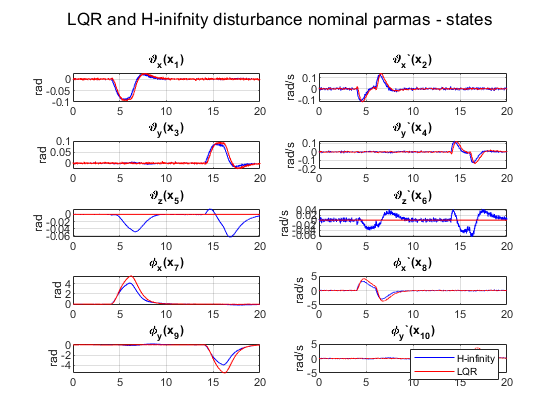

kill_figures([303,304,305,306]);
linsim(lft(P,-K_hinf),'b',dist,t_d,303,304);
linsim(lft(P,-K_lqr),'r',dist,t_d,303,304);
figure(303)
sgtitle('LQR and H-inifnity disturbance nominal parmas - states')
legend('H-infinity','LQR')

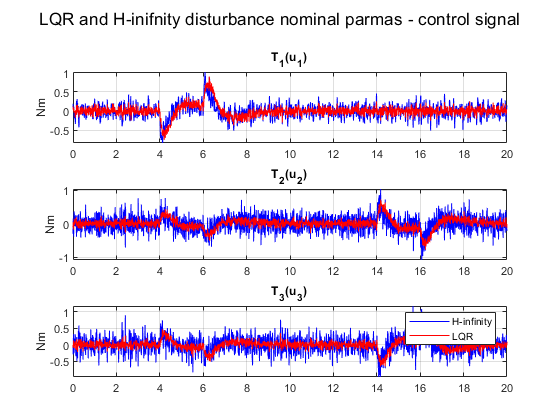

figure(304)
sgtitle('LQR and H-inifnity disturbance nominal parmas - control signal')
legend('H-infinity','LQR')

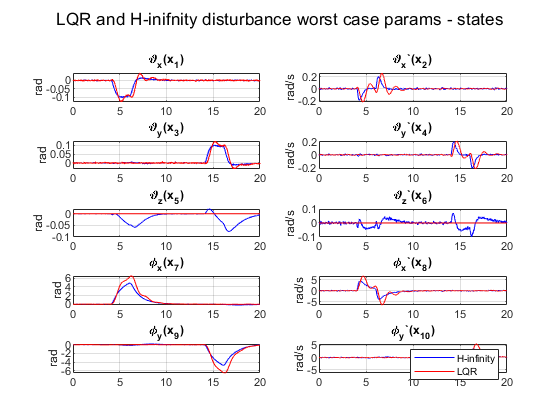

linsim(lft(P_wc,-K_hinf),'b',dist,t_d,305,306);
linsim(lft(P_wc,-K_lqr),'r',dist,t_d,305,306);
figure(305)
sgtitle('LQR and H-inifnity disturbance worst case params - states')
legend('H-infinity','LQR')

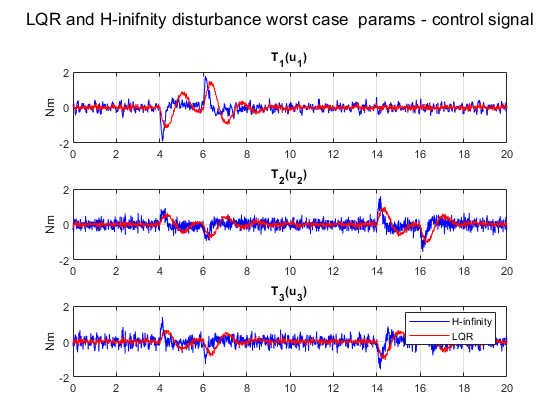

figure(306)
sgtitle('LQR and H-inifnity disturbance worst case  params - control signal')
legend('H-infinity','LQR')

### Bode diagram of comparison 

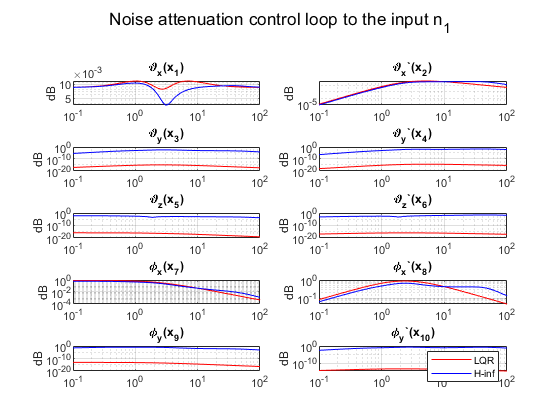

kill_figures([312,311]);
H_lqr = lft(P,-K_lqr);
H_hinf = lft(P,-K_hinf);
bodemg(H_lqr(1:10,1),'r',311);
hold on
bodemg(H_hinf(1:10,1),'b',311);
legend('LQR', 'H-inf')
sgtitle('Noise attenuation control loop to the input n_1');

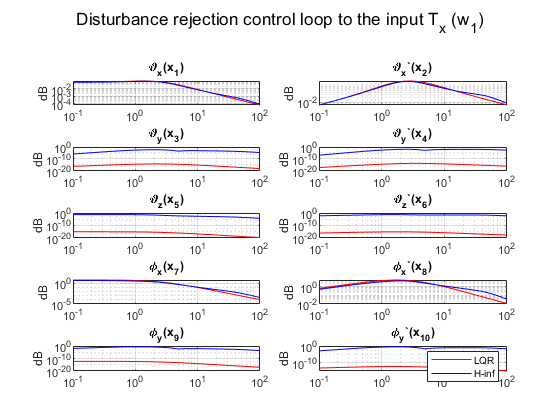


bodemg(H_lqr(1:10,5),'r',312);
hold on
bodemg(H_hinf(1:10,5),'b',312);
legend('LQR', 'H-inf')
sgtitle('Disturbance rejection control loop to the input T_x (w_1)');

## Complarison H-infinity and nonlinear model

kill_figures([307,308,309,310]);

Figure 310 not opened


nlsim(@nlin_model_n,-K_hinf,dist,t_d,P_wc,307,308);

nonlinear system simulation
Nonlinear simulation: 20.00 sec / 20.00 sec
Elapsed time is 38.388313 seconds.


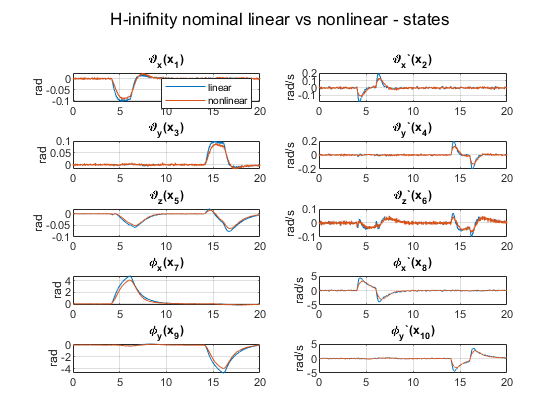

figure(307);
sgtitle('H-inifnity nominal linear vs nonlinear - states')

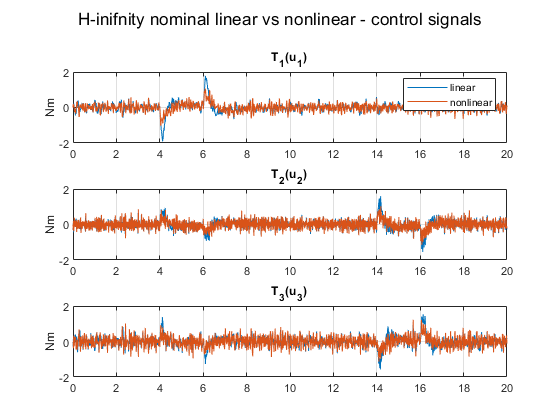

figure(308)
sgtitle('H-inifnity nominal linear vs nonlinear - control signals')

nlsim(@nlin_model_wcu,-K_hinf,dist,t_d,P,309,310);

nonlinear system simulation
Nonlinear simulation: 20.00 sec / 20.00 sec
Elapsed time is 38.164022 seconds.


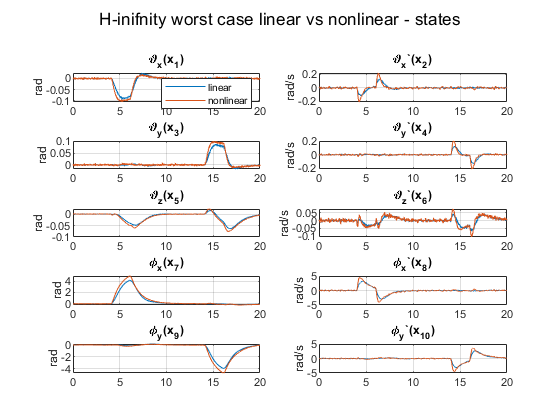

figure(309)
sgtitle('H-inifnity worst case linear vs nonlinear - states')

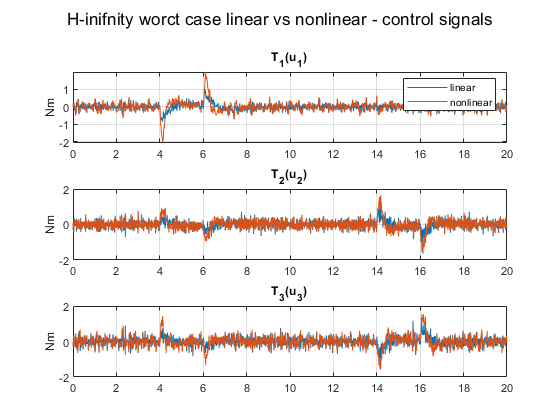

figure(310)
sgtitle('H-inifnity worct case linear vs nonlinear - control signals')

## State space H-infinity controller 

State space controller

%% H-infinity controller 
ns = 3;
A_tun = realp('A_t',rand(ns,ns));  
A_tun.Minimum = -100*ones(ns,ns); 
A_tun.Maximum = 100*ones(ns,ns);
B_tun = realp('B_t',rand(ns,10));   
B_tun.Minimum = -100*ones(ns,10); 
B_tun.Maximum = 100*ones(ns,10);
C_tun = realp('C_t',rand(3,ns));   
C_tun.Minimum = -100*ones(3,ns); 
C_tun.Maximum = 100*ones(3,ns);
D_tun = realp('D_t',rand(3,10));   
D_tun.Minimum = -100*ones(3,10); 
D_tun.Maximum = 100*ones(3,10);
opts = hinfstructOptions('TargetGain',0,'MaxIter',1000,'RandomStart',20,'MaxFrequency',10);
K_tun = ss(A_tun,B_tun,C_tun,D_tun);
[C,gamma,info] = hinfstruct(Pz_wc,K_tun,opts);

Final: Failed to enforce closed-loop stability (max Re(s) = 0.52)
Final: Peak gain = 24.3, Iterations = 499
Final: Peak gain = 10.4, Iterations = 482
Final: Peak gain = 26.5, Iterations = 507
Final: Peak gain = 6.19, Iterations = 660
Final: Peak gain = 5.49, Iterations = 760
Final: Peak gain = 13, Iterations = 443
Final: Peak gain = 7.67, Iterations = 599
Final: Peak gain = 6.47, Iterations = 711
Final: Peak gain = 6.12, Iterations = 824
Final: Peak gain = 9.87, Iterations = 609
Final: Peak gain = 11.2, Iterations = 481
Final: Peak gain = 20.4, Iterations = 349
Final: Peak gain = 50.4, Iterations = 363
Final: Peak gain = 12.3, Iterations = 427
Final: Peak gain = 9.41, Iterations = 589
Final: Peak gain = 5.48, Iterations = 635
Final: Peak gain = 6.12, Iterations = 737
Final: Peak gain = 5.4, Iterations = 740
Final: Peak gain = 27.6, Iterations = 370
Final: Peak gain = 6.15, Iterations = 796


K_hinf_ss = ss(C.Blocks.A_t.Value,C.Blocks.B_t.Value,C.Blocks.C_t.Value,C.Blocks.D_t.Value)


K_hinf_ss =
 
  A = 
           x1      x2      x3
   x1   42.26   12.68  -12.52
   x2   8.638   12.48  -25.87
   x3  -19.89    16.5   -17.3
 
  B = 
            u1       u2       u3       u4       u5       u6       u7       u8       u9      u10
   x1   -28.57   -34.58    97.03    99.99   -53.22    21.82    -93.7   0.4326    3.487   -2.587
   x2    99.93   -14.58     25.3    61.32   -68.89   -0.374   -78.91   -4.688    38.47    2.613
   x3    66.71  -0.3908    -71.7   -80.43    32.28   -16.37    28.93   -4.897    2.534   -1.966
 
  C = 
           x1      x2      x3
   y1   -7.05   30.74  -32.33
   y2  -2.521  -18.39    25.3
   y3   29.73   2.164   1.957
 
  D = 
           u1      u2      u3      u4      u5      u6      u7      u8      u9     u10
   y1  -99.98    -100   21.47  -19.08   12.77  -2.906  -11.46  -6.555     8.1  -6.022
   y2   18.18   57.74  -45.88  -39.22   31.32  -1.496   44.71   3.777  -21.72   1.802
   y3   94.95   42.23   29.04   39.26   -25.3   9.276   -43.6   3.071

## Comparison LQR and H-inifnity state space

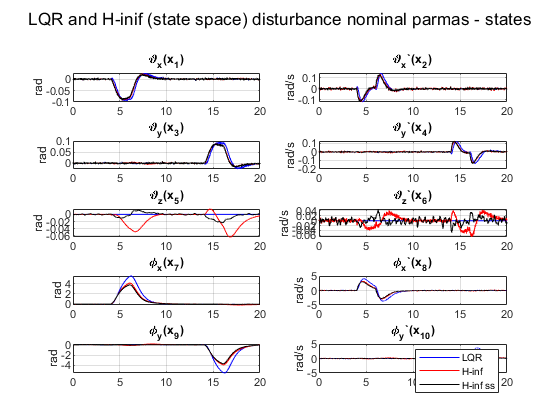

kill_figures([404,405,406,407]);
linsim(lft(P,-K_lqr),'b',dist,t_d,404,405);
linsim(lft(P,-K_hinf),'r',dist,t_d,404,405);
linsim(lft(P,K_hinf_ss),'k',dist,t_d,404,405);
figure(404)
sgtitle('LQR and H-inif (state space) disturbance nominal parmas - states')
legend('LQR','H-inf','H-inf ss')

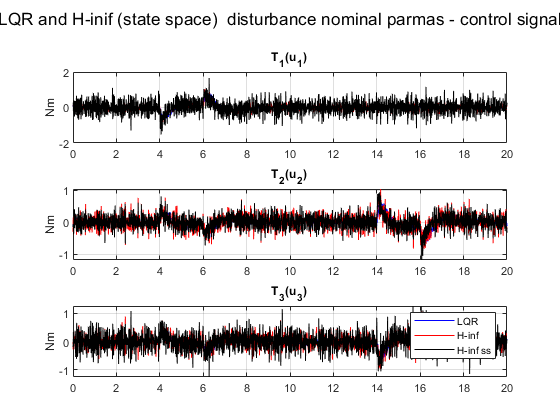

figure(405)
sgtitle('LQR and H-inif (state space)  disturbance nominal parmas - control signal')
legend('LQR','H-inf','H-inf ss')

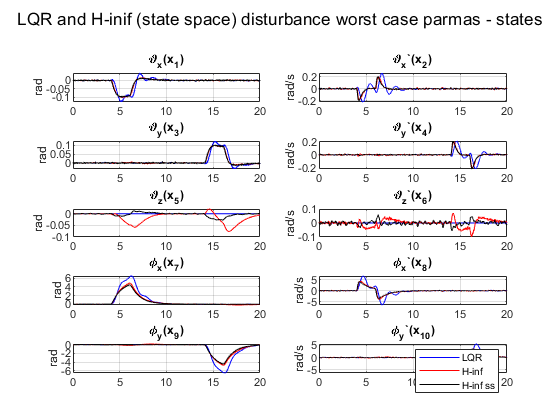

linsim(lft(P_wc,-K_lqr),'b',dist,t_d,406,407);
linsim(lft(P_wc,-K_hinf),'r',dist,t_d,406,407);
linsim(lft(P_wc,K_hinf_ss),'k',dist,t_d,406,407);
figure(406)
sgtitle('LQR and H-inif (state space) disturbance worst case parmas - states')
legend('LQR','H-inf','H-inf ss')

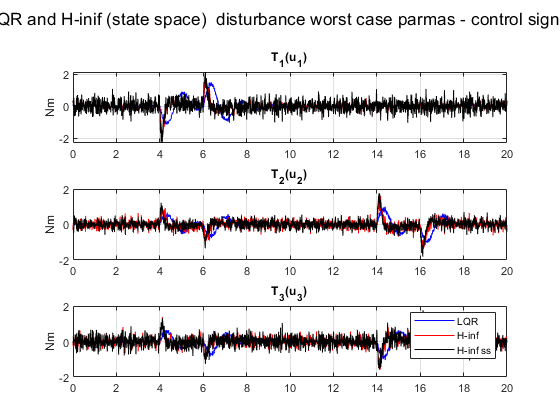

figure(407)
sgtitle('LQR and H-inif (state space)  disturbance worst case parmas - control signal')
legend('LQR','H-inf','H-inf ss')

## Complarison H-infinity and nonlinear model

kill_figures([507,508,509,510]);
nlsim(@nlin_model_n,K_hinf_ss,dist,t_d,P_wc,507,508);

nonlinear system simulation
Nonlinear simulation: 20.00 sec / 20.00 sec
Elapsed time is 42.277997 seconds.


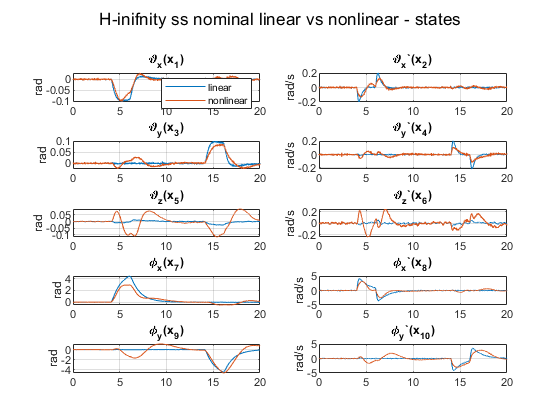

figure(507);
sgtitle('H-inifnity ss nominal linear vs nonlinear - states')
hold off;

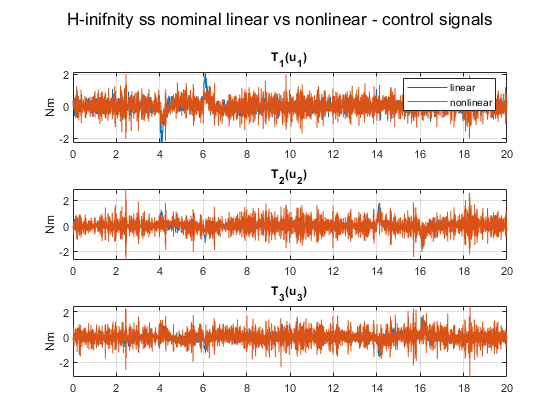

nonlinear system simulation
Nonlinear simulation: 20.00 sec / 20.00 sec
Elapsed time is 42.206991 seconds.


figure(508)
sgtitle('H-inifnity ss nominal linear vs nonlinear - control signals')
hold off;
nlsim(@nlin_model_wcu,K_hinf_ss,dist,t_d,P,509,510);

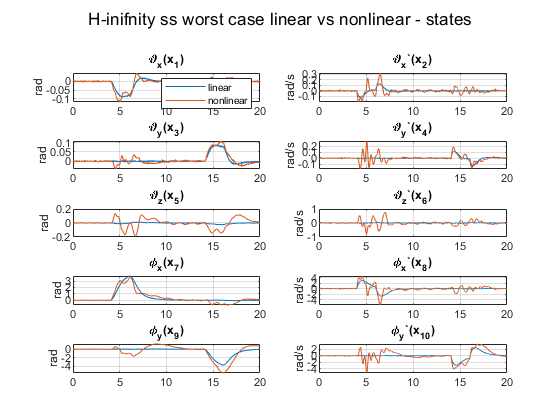


figure(509)
sgtitle('H-inifnity ss worst case linear vs nonlinear - states')

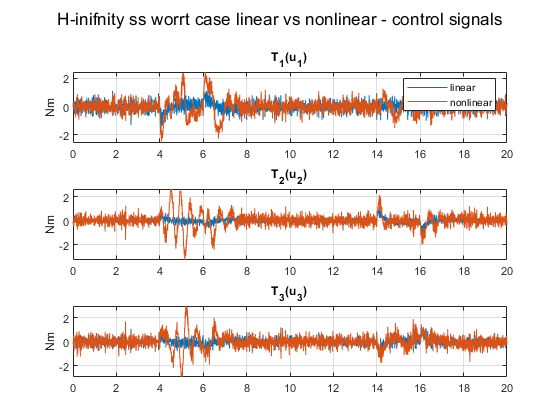

figure(510)
sgtitle('H-inifnity ss worrt case linear vs nonlinear - control signals')

## Bode diagram of LQR, H-infinity gain and H-infinity state space

We can see that state space H-infinity controller has lowest gain for almost all the transfrer functions on the plot making it the most robustly stable one.

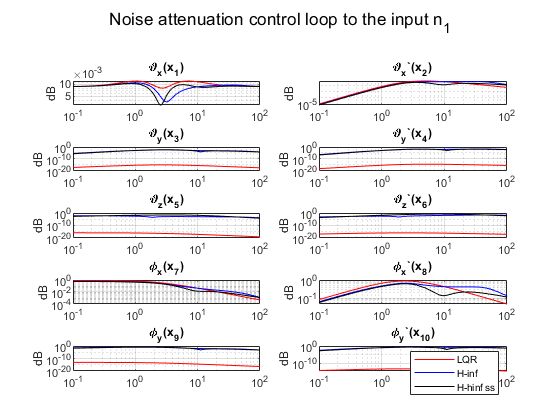

kill_figures([506,512]);
figure(506)
H_hinf_ss = lft(P,K_hinf_ss);
bodemg(H_lqr(1:10,1),'r',506);
hold on
bodemg(H_hinf(1:10,1),'b',506);
bodemg(H_hinf_ss(1:10,1),'k',506);
legend('LQR', 'H-inf', 'H-hinf ss')
sgtitle('Noise attenuation control loop to the input n_1');

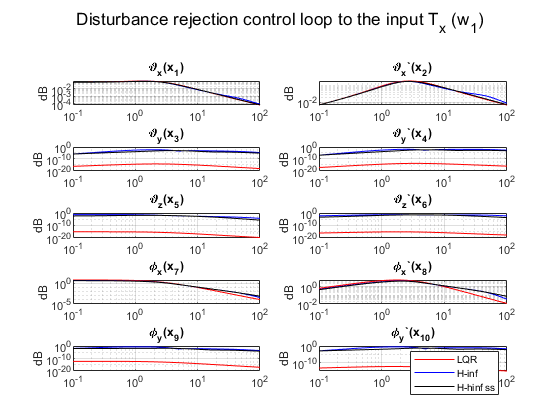

bodemg(H_lqr(1:10,5),'r',512);
hold on
bodemg(H_hinf(1:10,5),'b',512);
bodemg(H_hinf_ss(1:10,5),'k',512);
legend('LQR', 'H-inf','H-hinf ss')
sgtitle('Disturbance rejection control loop to the input T_x (w_1)');

## H-infintiy norms for nominal and worst case parameter linear model comparison of LQR, fixed H-inifnity and state space H-Infinity controller

hinfnorm(lft(P,-K_lqr))

ans = 6.9632

hinfnorm(lft(P,-K_hinf))

ans = 5.3480

hinfnorm(lft(P,K_hinf_ss))

ans = 4.8838

hinfnorm(lft(P_wc,-K_lqr))

ans = 14.4496

hinfnorm(lft(P_wc,-K_hinf))

ans = 5.9559

hinfnorm(lft(P_wc,K_hinf_ss))

ans = 5.3383

## Stability margins for nominal and worst case parameter linear model comparison of LQR, fixed H-inifnity and state space H-Infinity controller

diskmargin(G_n,K_lqr)

ans = struct with fields:
     GainMargin: [0.8536 1.1715]
    PhaseMargin: [-9.0299 9.0299]
     DiskMargin: 0.1579
     LowerBound: 0.1579
     UpperBound: 0.1582
      Frequency: 3.5389


diskmargin(G_n,K_hinf)

ans = struct with fields:
     GainMargin: [0.8670 1.1534]
    PhaseMargin: [-8.1494 8.1494]
     DiskMargin: 0.1425
     LowerBound: 0.1425
     UpperBound: 0.1428
      Frequency: 42.6120


diskmargin(G_n,-K_hinf_ss)

ans = struct with fields:
     GainMargin: [0.9203 1.0865]
    PhaseMargin: [-4.7504 4.7504]
     DiskMargin: 0.0830
     LowerBound: 0.0830
     UpperBound: 0.0831
      Frequency: 3.3194


diskmargin(wcu.G,K_lqr)

ans = struct with fields:
     GainMargin: [0.9540 1.0482]
    PhaseMargin: [-2.6971 2.6971]
     DiskMargin: 0.0471
     LowerBound: 0.0471
     UpperBound: 0.0472
      Frequency: 4.4176


diskmargin(wcu.G,K_hinf)

ans = struct with fields:
     GainMargin: [0.9333 1.0715]
    PhaseMargin: [-3.9546 3.9546]
     DiskMargin: 0.0690
     LowerBound: 0.0690
     UpperBound: 0.0692
      Frequency: 12.6485


diskmargin(wcu.G,-K_hinf_ss)

ans = struct with fields:
     GainMargin: [0.9543 1.0478]
    PhaseMargin: [-2.6768 2.6768]
     DiskMargin: 0.0467
     LowerBound: 0.0467
     UpperBound: 0.0472
      Frequency: 10.0712


## Closed loop singular value plot comparison

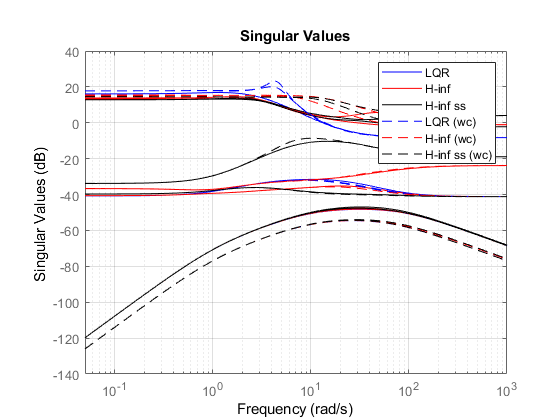

% plot singular values of distrurbance rejection loop
figure(520)
sigma(lft(P,-K_lqr),'b',lft(P,-K_hinf),'r',lft(P,K_hinf_ss),'k',lft(P_wc,-K_lqr),'--b',lft(P_wc,-K_hinf),'--r',lft(P_wc,K_hinf_ss),'--k',(0.05:0.01:1000));
legend('LQR','H-inf','H-inf ss','LQR (wc)','H-inf (wc)','H-inf ss (wc)');
grid on;